clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
OD_circle_image_path = fullfile('fundus_images');
load('meanHistRGB9.mat');%esto te da la variable MeanHistRGB
vignette=double(rgb2gray(imread('viñeta2.jpg')));
vignette=vignette./max(vignette(:));

factor_reduccion = 1/10; 
dimensiones_nuevas = [2425, 3005];%Para que todas las imagenes entren al for con el mismo tamaño
margen=300/10;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas

tR=0.5;
tG=2;
tB=1;


Hago la matriz del círculo:

margen_zoom=430;
se = strel('disk',100);

indices = find(T.quality == 4);

n = (2*margen_zoom)+1;
[x, y] = meshgrid(-n/2:n/2-1, -n/2:n/2-1);
distancia = sqrt(x.^2 + y.^2);
radio = n/2;
circulo = distancia <= radio;
circulo=double(circulo);

STEP 1. LOCALIZO EL OD Y HAGO CIRCLE

%for u = 1:length(indices)
%    k=indices(u);
    % Leer la imagen original

k=30;%cambia esto
RGB = imread(string(fullfile(img_path, T{k,1})));%Voy a buscar el OD de esta imagen
RGB(:,:,1)=medfilt2(RGB(:,:,1),[3 3],"symmetric");
RGB(:,:,2)=medfilt2(RGB(:,:,2),[3 3],"symmetric");
RGB(:,:,3)=medfilt2(RGB(:,:,3),[3 3],"symmetric");

[media_izquierda,media_derecha]=medias(RGB,se);

if (media_derecha > 100) || (media_izquierda > 100)%si detecta que esta quemado (media>100) ejecuta el código)
       [RGB_sinQuemado]=oscurecerQuemados(RGB, vignette);

    [media_izquierda,media_derecha]=medias(RGB_sinQuemado,se);
    if (media_derecha > 100) || (media_izquierda > 100)
        [RGB_sinQuemado]=oscurecerQuemados(RGB_sinQuemado, vignette);
    end

else
    RGB_sinQuemado=uint8(RGB);
end

RGB=uint8(RGB);

%Aquí en vez de hacer dos cambios se podría poner uno y ya, hay que
%mirarlo...
[alto_original, ancho_original, ~] = size(RGB_sinQuemado);
imagen_redimensionada = imresize(RGB_sinQuemado, dimensiones_nuevas);
new_size = [size(imagen_redimensionada, 1) * factor_reduccion, size(imagen_redimensionada, 2) * factor_reduccion];
RGBa = imresize(imagen_redimensionada, new_size, 'bicubic');

[alto, ancho, ~] = size(RGBa);
CM=zeros(alto-margen*2,ancho-margen*2);
diff=zeros(alto-margen*2,ancho-margen*2);
dif=zeros(alto-margen*2,ancho-margen*2,3);

for i=1:3
    for x=margen+1:ancho-margen
        for y=margen+1:alto-margen
            layer_zoom=RGBa(y-margen:y+margen, x-margen:x+margen, i);
            [hist_layer, ~] = imhist(layer_zoom);
            diff(y-margen,x-margen)=sum(bsxfun(@minus, hist_layer, meanHistRGB(i)).^2);
        end
        
    end
    dif(:,:,i)=diff;
end

c=1/(1+dif);
CM = c(:,:,1).*tR + c(:,:,2).*tG + c(:,:,3);
CM_padded = padarray(CM, [margen margen], 0);%como no se ha puesto un margen, ahora hay que hacerle un padding pa sumárselo
CM_padded_redimensioned = imresize(CM_padded, [alto_original ancho_original]);
thres=CM_padded_redimensioned>0.93*max(CM_padded_redimensioned(:));

Utilizando en vez del máximo, el 0,98 máximo y calculando el centroide

[row, col] = find(thres);%Busca los elementos no 0
centroideX = round(mean(col)); %lo redondeo porque lo que quiero es la posición de un pixel, tiene que ser integer
centroideY = round(mean(row));

Ahora voy a conseguir un circulo con el OD dentro

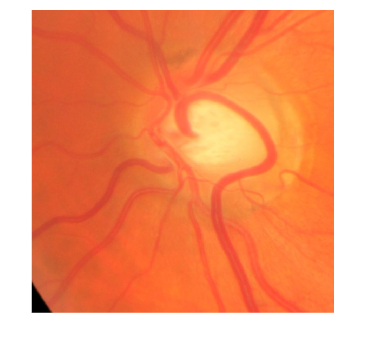

if centroideY+margen_zoom>height(RGB)
   centroideY=height(RGB)-margen_zoom;
elseif centroideY-margen_zoom<1
    centroideY=margen_zoom+1;
end

if centroideX+margen_zoom>width(RGB)
   centroideX=width(RGB)-margen_zoom;
elseif centroideX-margen_zoom<1
    centroideX=margen_zoom+1;
end

OD_zoomR=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,1);
OD_zoomG=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,2);
OD_zoomB=RGB(centroideY-margen_zoom:centroideY+margen_zoom, centroideX-margen_zoom:centroideX+margen_zoom,3);

OD_zoomR=double(OD_zoomR);
OD_zoomG=double(OD_zoomG);
OD_zoomB=double(OD_zoomB);

OD_zoomRGB = cat(3, OD_zoomR, OD_zoomG, OD_zoomB);%Para juntar las 3 layers

OD_zoomRGB=uint8(OD_zoomRGB);

% Guardar la imagen modificada en el directorio correspondiente
%nombre_archivo = cell2mat(fullfile(OD_circle_image_path, T{k,1})); 
%imwrite(OD_circleRGB, nombre_archivo);
%end
figure;
imshow(OD_zoomRGB);

desviacion_estandar=std(OD_zoomR(:))

desviacion_estandar = 20.5377

entropia=entropy(OD_zoomR)

entropia = 0.0228

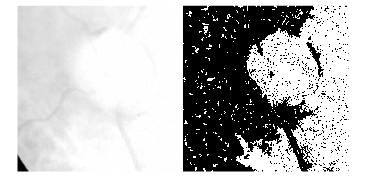

BW=imextendedmax(OD_zoomR,2);
figure;
imshowpair(OD_zoomR,BW,'montage');

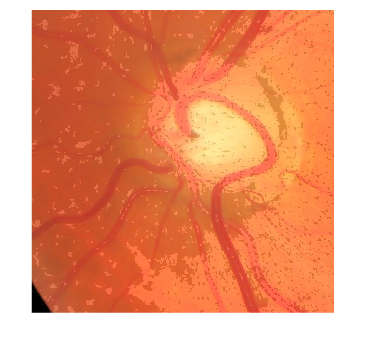


figure;
transparencia=0.1;
imshow(OD_zoomRGB);
hold on;
h=imshow(BW);
set(h,'AlphaData', transparencia);
hold off;

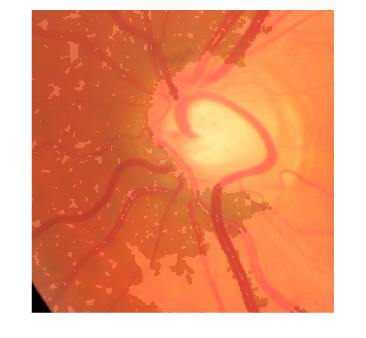

se = strel('disk',1);
BW1 = imerode(BW,se);
BW2 = imfill(BW1,'holes');
BW3 = imdilate(BW2,se);
BW4 = imfill(BW3,'holes');
BW5 = imdilate(BW4,se);
BW6 = imfill(BW5,'holes');
BW7 = imdilate(BW6,se);
BW8 = imfill(BW7,'holes');
BW9 = imerode(BW8,se);
BW10 = imerode(BW9,se);
se = strel('disk',5);
BW11 = imclose(BW10,se);

figure;
transparencia=0.1;
imshow(OD_zoomRGB);
hold on;
h=imshow(BW11);
set(h,'AlphaData', transparencia);
hold off;

figure;
imshow(OD_zoomRGB);
stats = regionprops("table",BW11,"Centroid", ...
    "MajorAxisLength","MinorAxisLength","Orientation","Eccentricity","Circularity")

stats = 221×6 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Circularity
    ________________    _______________    _______________    ____________    ___________    ___________

     2.913    197.74         6.433             4.9064           0.64675          33.913        0.87241  
    7.2911    382.93        26.186             13.139             0.865          71.144        0.45699  
       2.1    539.55        7.2041             3.9201           0.83899         -77.152        0.78189  
     13.11    608.04        25.846             19.796           0.64296          7.7578        0.76876  
       1.4     801.5        6.1101             2.2745           0.92813              90        0.69676  
         9       406        8.7679      

stats( stats.MajorAxisLength > 1000 | stats.MinorAxisLength < 300, : ) = []%he puesto esta linea que la he sacado de otro código, está 100x100 mal. Hay que poner and en vez de or!!!!!

stats = 1×6 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Circularity
    ________________    _______________    _______________    ____________    ___________    ___________

    667.74    402.84        873.22             517.89           0.80515         -79.919        0.29452  


centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;%he usado el min axis en vez de diameter
hold on
viscircles(centers,radii)%aquí busca una manera de poder dibujar elipses en vez de circulos

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


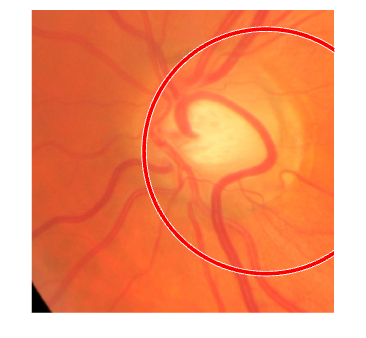

hold off

EN el caso de que pille bien el radio pero no la posición he pensado en hacer un for que vaya recorriendo toda a imagen y calculando o el brillo que tiene (si lo haces en OD_zoom) o el número de 1 (si lo haces en BW). Donde mayor valor haya es el centro real.